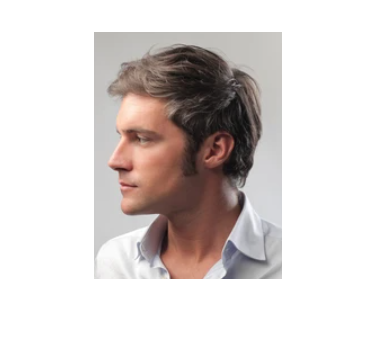

clear ALL
clf

% Input image, the image which will be reproduced
inputImage = imread('../images-to-reproduce/Face.png');
imshow(inputImage)

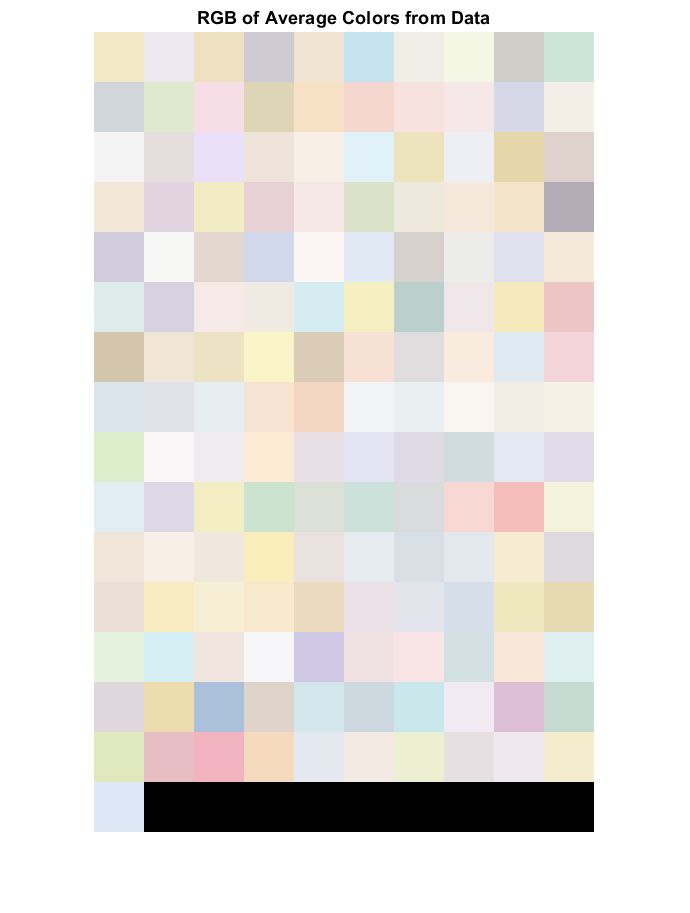


% The data containing all of the smaller images
folder = '../pokemon-images';
fileList = dir(fullfile(folder, '*.jpg'));

% The images are resized to blocksize x blocksize
images = cell(1, numel(fileList));
resized_images = cell(1, numel(fileList));
blocksize = 32;

% Uses showRGB to display all the average colors from the data 
dataBase_avgColors = zeros(numel(fileList), 3);  % Matrix to store average colors (R, G, B)

for i = 1:numel(fileList)
    filename = fullfile(folder, fileList(i).name);
    images{i} = im2double(imread(filename));
    resized_images{i} = imresize(images{i}, [blocksize, blocksize]);
    
    % Calculate average color for each channel (R, G, B)
    dataBase_avgColors(i, 1) = mean(mean(resized_images{i}(:,:,1)));  % Red channel
    dataBase_avgColors(i, 2) = mean(mean(resized_images{i}(:,:,2)));  % Green channel
    dataBase_avgColors(i, 3) = mean(mean(resized_images{i}(:,:,3)));  % Blue channel
end

figure;
showRGB(dataBase_avgColors);
title('RGB of Average Colors from Data');

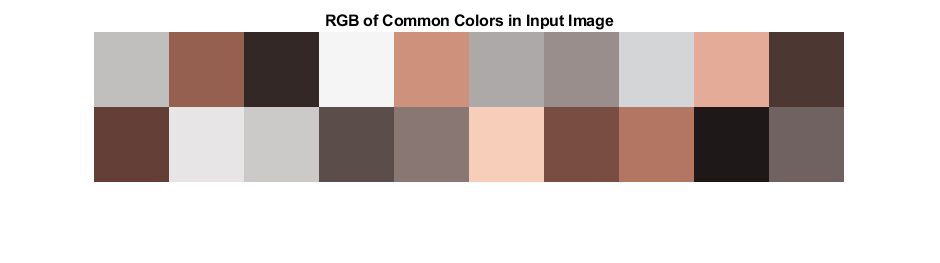


% Convert the input image to a matrix of RGB values
inputImageSize = size(inputImage);
inputImageMatrix = im2double(reshape(inputImage, [], 3));

% Perform k-means clustering to find the most common colors with increased iterations
num_colors = 20;
opts = statset('MaxIter', 1000);  % Increase the maximum number of iterations
[idx, inputImage_commonColors] = kmeans(inputImageMatrix, num_colors, 'Options', opts);

% Show RGB of common colors in the input image
figure;
showRGB(inputImage_commonColors);
title('RGB of Common Colors in Input Image');

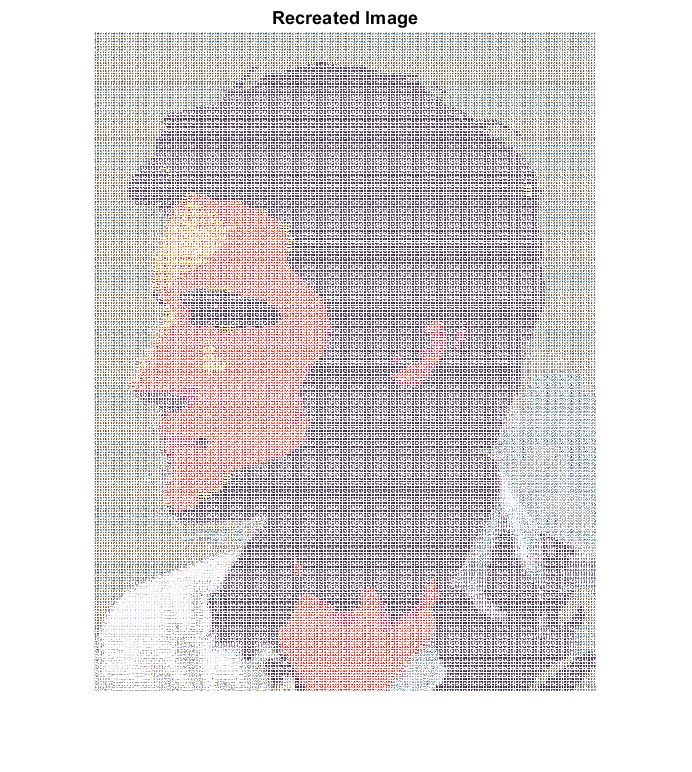


% ********************************** Calculating closest colors ************************************

% Converts to XYZ (Device independent format)
dataBase_avgColors_XYZ = rgb2xyz(dataBase_avgColors);
% Convert the average colors from the data to LAB
dataBase_avgColors_LAB = xyz2lab(dataBase_avgColors_XYZ);

% Converts to XYZ (Device independent format)
inputImage_commonColors_XYZ = rgb2xyz(inputImage_commonColors);
% Convert the common colors from the input image to LAB
inputImage_commonColors_LAB = xyz2lab(inputImage_commonColors_XYZ);

% Initialize matrices to store the mean and max DeltaE values
meanDeltaE_matrix = zeros(inputImageSize(1), inputImageSize(2));
maxDeltaE_matrix = zeros(inputImageSize(1), inputImageSize(2));

% Initialize the OUTPUTIMAGE
outputImageSize = inputImageSize * blocksize;
outputImage = zeros(outputImageSize(1), outputImageSize(2), 3);

% Iterate through each block in the OUTPUTIMAGE
for row = 1:blocksize:outputImageSize(1)
    for col = 1:blocksize:outputImageSize(2)
        % Extract LAB values of the current block from INPUTIMAGE
        inputBlockLab = rgb2lab(reshape(inputImage(ceil(row/blocksize), ceil(col/blocksize), :), 1, 1, 3));

        % Initialize variables to store closest image information
        closestImageIdx = 0;
        minMeanDeltaE = inf;

        % Iterate through each image in the DATABASE
        for i = 1:numel(fileList)
            % Extract LAB values of the current image from DATABASE
            databasePixelLab = dataBase_avgColors_LAB(i, :);

            % Calculate meanDeltaE between the input block and the current image
            [meanDeltaE, ~] = meanAndMaxDeltaE(inputBlockLab, databasePixelLab);

            % Update closest image information if the current image is closer
            if meanDeltaE < minMeanDeltaE
                minMeanDeltaE = meanDeltaE;
                closestImageIdx = i;
            end
        end

        % Replace the block in OUTPUTIMAGE with the corresponding block from the closest image
        outputImage(row:(row+blocksize-1), col:(col+blocksize-1), :) = resized_images{closestImageIdx};
    end
end

% Display the OUTPUTIMAGE
figure;
imshow(outputImage);
title('Recreated Image');


% Save the OUTPUTIMAGE
outputImagePath = 'Recreated_Image.png';
imwrite(outputImage, outputImagePath);








